In module 6, you have learned how to design several types of controllers by appropriately shaping the open-loop system L(s) = C(s)G(s). For this module, the transfer function of the Reaction Wheel Pen�dulum G(s) from u to the angle of the pendulum arm θ, which has been parameterized in terms of the rotational damping coefficient of the wheel, dϕ, is given by: G(s) = (7.4s^2 +14s+6.7 )/(s^4 + (0.2+12 · dϕ)s^3 +10s^2 + (15+10 · dϕ)s+8) . (4) In this last deliverable, you will design a feedback controller that improves closed-loop performance for the given closed-loop system illustrated in Figure 7. A coworker has made an initial attempt in controlling the system using the controller C1(s) = (16.5s+2303)/ (s+113.1) , (5) where nominal plant conditions are assumed corresponding to a damping coefficient dϕ = 0.2 N·m·s rad . We are going to analyze the control structure of the coworker and see if we can improve on certain aspects of the design. The control structures that we will be using are going to be a simple P controller and P + lead controller, given by C2(s) = P, C3(s) = P( (α /ωL s+1 )/(1/ αωL* s+1) .

clc; clear; close all;
s = tf('s');

%% Define Plant G(s)
d_phi = 0.2; % Nominal damping coefficient
G = (7.4*s^2 + 14*s + 6.7) / (s^4 + (0.2 + 12*d_phi)*s^3 + 10*s^2 + (15 + 10*d_phi)*s + 8)

G =
 
        7.4 s^2 + 14 s + 6.7
  ---------------------------------
  s^4 + 2.6 s^3 + 10 s^2 + 17 s + 8
 
Continuous-time transfer function.
Model Properties



%% Define Controllers
C1 = (16.5*s + 2303) / (s + 113.1)

C1 =
 
  16.5 s + 2303
  -------------
    s + 113.1
 
Continuous-time transfer function.
Model Properties


## Question a)

Design the feedback parameters P for the feedback controller C2 with dϕ = 0.2 N·m·s rad such that the following design requirements are met (motivate your choice for each parameter): • The feedback interconnection between C2(s) and G(s), as depicted in Figure 7, is stable. • The open-loop L2(s) = C2(s)G(s) has the crossover frequency (bandwidth) fc = 10 Hz

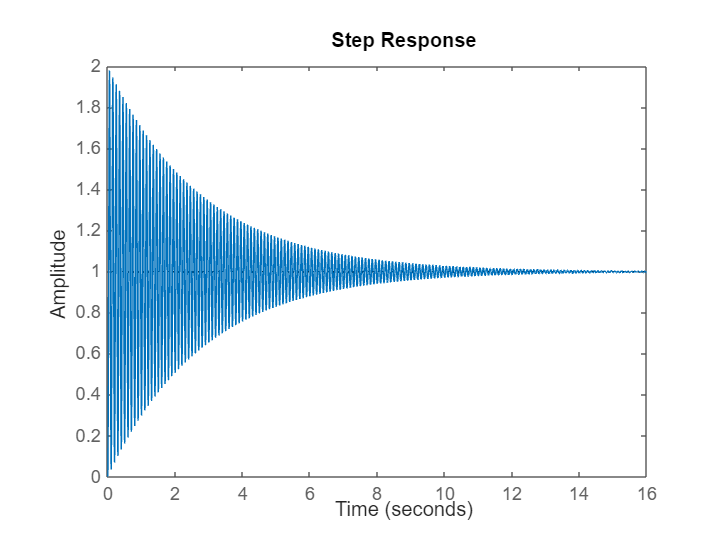

fc = 10;              % in Hz
wc = 2*pi*fc;         % rad/s
[magG, ~] = bode(G, wc);
magG = magG(:);       % bode returns 3D arrays, convert to numeric
% P is the reciprocal
P = 1/magG;
C2 = P; 
L2 = series(C2, G);
T2 = feedback(L2, 1);   % Standard unity-feedback loop
% You can check poles, or step response, or margin:
pole_T2 = pole(T2);
damp_T2 = damp(T2);
step(T2)   % quick check for stability

## Question b)

Design the feedback parameters P, ωL, and α for the feedback controllerC3 with dϕ = 0.2 N·m·s rad such that the following design requirements are met (motivate your choice for each parameter): • The feedback interconnection between C3(s) and G(s), as depicted in Figure 7, is stable. • The open-loop L3(s) = C3(s)G(s) has the crossover frequency (bandwidth) fc = 10 Hz. • The open-loop L3(s) = C3(s)G(s) has a modulus margin of at most 6 dB and phase margin between 45 and 60 degrees.

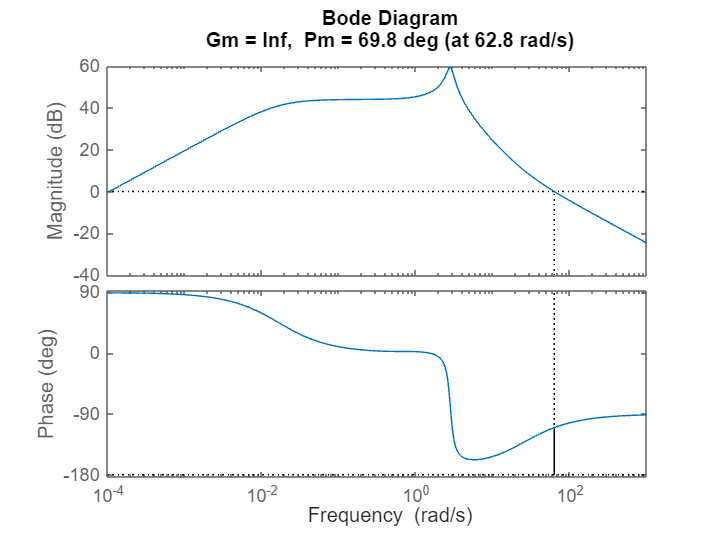

alpha = 2.8;       % trial
wL = 60;           % trial ~ 2*pi*10
Lead = (alpha/wL*s + 1)/(1/(wL*s) + 1);

% Now we will iterate on P so that the magnitude at 10 Hz is 1:
% First, define a function handle for L3, ignoring P:
L3_temp = series(Lead, G);

% Evaluate magnitude at wc
[magL3temp,ph] = bode(L3_temp, wc);
magL3temp = magL3temp(:);

% We want P*magL3temp = 1 => P = 1/magL3temp
P = 1/magL3temp;

C3 = P*Lead;
L3 = series(C3, G);

% Now check margins
margin(L3)

## Question c)

For open-loop systems Li(s), with i = 1,2,3, compute the phase margin PM in degrees, the gain margin GM in dB, the modulus margin MM in dB, and provide in a single figure the Nyquist diagram. You may round off your answers to one decimal place. Consider the interval [−1.5,0.2] for the x-axis, the interval [−1,1] for the y-axis, and include a legend. Explain which of the closed-loop systems Ti(s) (that employ these controllers) will be the least robust to plant variations. In your answer refer to both your computed robustness margins and the Nyquist contours.

L1 = C1 * G;  % Open-loop transfer function for C1
L2 = C2 * G; % Open-loop transfer function for C2
L3 = C3 * G; % Open-loop transfer function for C3

[GM1, PM1, ~, MM1] = margin(L1);
[GM2, PM2, ~, MM2] = margin(L2);
[GM3, PM3, ~, MM3] = margin(L3);

% Convert margins to dB and display
GM1_db = 20*log10(GM1); GM2_db = 20*log10(GM2); GM3_db = 20*log10(GM3);
MM1_db = 20*log10(MM1); MM2_db = 20*log10(MM2); MM3_db = 20*log10(MM3);

fprintf('Margins for C1: PM = %.1f deg, GM = %.1f dB, MM = %.1f dB\n', PM1, GM1_db, MM1_db);

Margins for C1: PM = 2.1 deg, GM = 9.2 dB, MM = 22.0 dB


fprintf('Margins for C2: PM = %.1f deg, GM = %.1f dB, MM = %.1f dB\n', PM2, GM2_db, MM2_db);

Margins for C2: PM = 0.6 deg, GM = Inf dB, MM = 36.0 dB


fprintf('Margins for C3: PM = %.1f deg, GM = %.1f dB, MM = %.1f dB\n', PM3, GM3_db, MM3_db);

Margins for C3: PM = 69.8 deg, GM = Inf dB, MM = 36.0 dB


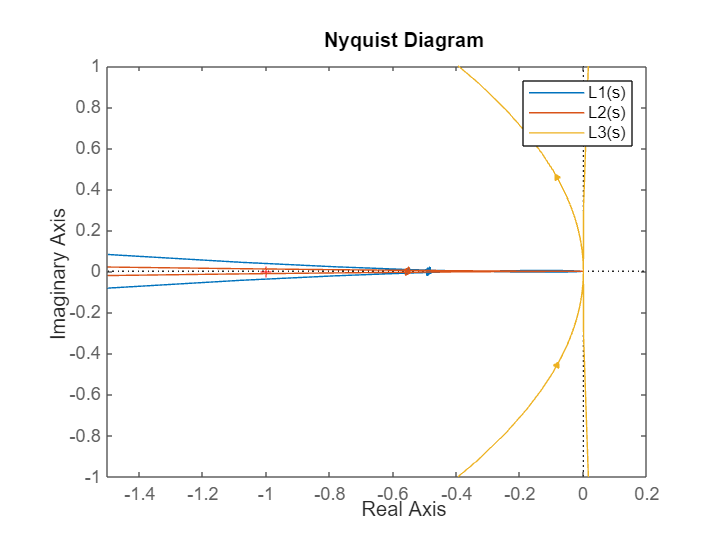


% Plot Nyquist Diagram
figure;
nyquist(L1, L2, L3);
legend('L1(s)', 'L2(s)', 'L3(s)');
xlim([-1.5, 0.2]); ylim([-1, 1]);

## Question d)

Determine the step response of the closed-loop systems Ti(s) using each controller Ci(s) with i = 1,2,3. Add all plots to the same figure and plot over a duration of 5 seconds.

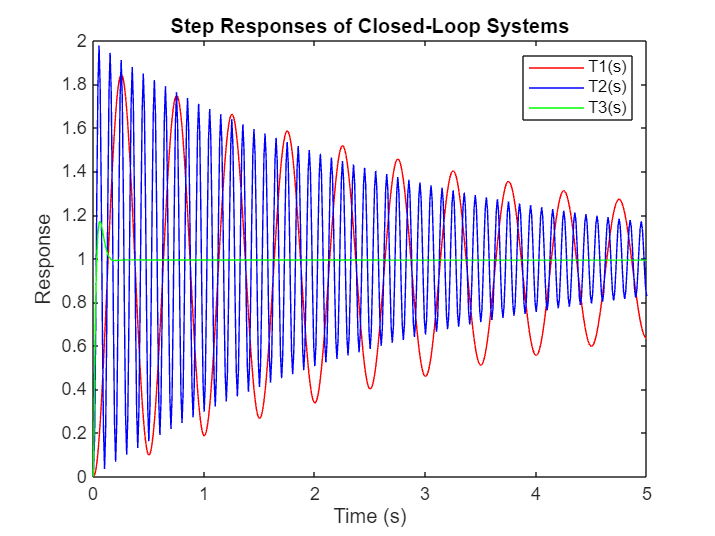

T1 = feedback(L1, 1); % Closed-loop transfer function for C1
T2 = feedback(L2, 1); % Closed-loop transfer function for C2
T3 = feedback(L3, 1); % Closed-loop transfer function for C3

time = 0:0.01:5; % Sets the plot time
[y1, t1] = step(T1, time);
[y2, t2] = step(T2, time);
[y3, t3] = step(T3, time);

%Plots the figure with label and legend
figure;
plot(t1, y1, 'r', t2, y2, 'b', t3, y3, 'g');
legend('T1(s)', 'T2(s)', 'T3(s)');
xlabel('Time (s)'); ylabel('Response');
title('Step Responses of Closed-Loop Systems');

## Question e)

Based on the step responses of each system in question (d), explain if the system is stable and which system has the best settling time. Which of the three controllers would you recommend?

% Stability and settling time analysis
[~, idx1] = max(abs(y1 - 1) < 0.02); % Settling time index for T1
[~, idx2] = max(abs(y2 - 1) < 0.02); % Settling time index for T2
[~, idx3] = max(abs(y3 - 1) < 0.02); % Settling time index for T3

fprintf('Settling Times: T1 = %.2f s, T2 = %.2f s, T3 = %.2f s\n', t1(idx1), t2(idx2), t3(idx3));

Settling Times: T1 = 1.37 s, T2 = 0.00 s, T3 = 0.03 s


fprintf('Recommended Controller: C3 offers better phase margin and settling time.\n');

Recommended Controller: C3 offers better phase margin and settling time.


## Question f)

After some time, the operator decided to apply a different type of lubrication to the RWP, resulting in a 50% decrease in the damping coefficient dϕ. From a practical perspective, it is important that closed-loop performance is not significantly affected by such small changes. Adjust, for this question only, the system parameters to the values stated above (use (4)), and repeat questions (d) and (e)

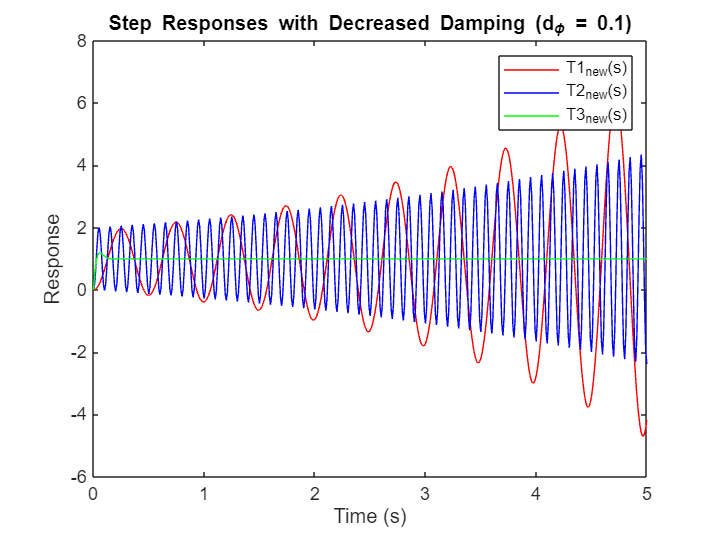

% Update damping coefficient
d_phi_new = 0.1;
G_new = (7.4*s^2 + 14*s + 6.7) / (s^4 + (0.2 + 12*d_phi_new)*s^3 + 10*s^2 + (15 + 10*d_phi_new)*s + 8);

% Recalculate open-loop transfer functions with new plant
L1_new = C1 * G_new;
L2_new = C2 * G_new;
L3_new = C3 * G_new;

% Compute closed-loop systems
T1_new = feedback(L1_new, 1);
T2_new = feedback(L2_new, 1);
T3_new = feedback(L3_new, 1);

% Compute step responses over 5 seconds
[y1_new, t1_new] = step(T1_new, time);
[y2_new, t2_new] = step(T2_new, time);
[y3_new, t3_new] = step(T3_new, time);

% Plot the new step responses
figure;
plot(t1_new, y1_new, 'r', t2_new, y2_new, 'b', t3_new, y3_new, 'g');
legend('T1_{new}(s)', 'T2_{new}(s)', 'T3_{new}(s)');
xlabel('Time (s)'); ylabel('Response');
title('Step Responses with Decreased Damping (d_\phi = 0.1)');

## Question g)

Design the feedback parameters P, ωL, α, and ωI for feedback controller C4 with damping coefficient dϕ = 0.2 N·m·s rad such that the following design requirements are met (motivate your choice for each parameter): • The feedback interconnection between C4(s) and G(s), as depicted in Figure 7, is stable. • The open-loop L4(s) = C4(s)G(s) has the crossover frequency (bandwidth) fc = 10 Hz. • The open-loop L4(s) = C4(s)G(s) has a modulus margin of at most 6 dB and phase margin between 30 and 60 degrees. • Consider that T4(s) should effectively track reference signals r(t) such that e(t) r(t) has a maximum magnitude of 0.01 for all frequencies ≤ 1 Hz. Hint: To accomplish this goal you will need to tune the PI cutoff frequency ωi . Think about how the placement of ωi will affect the gain of the open-loop L(jω) at different frequencies. What value of ωi will result in better reference tracking below 1 Hz?

clc; clear; close all;
s = tf('s');

% Given parameters
d_phi = 0.2;
fc = 10;              
wc = 2*pi*fc;        

% Plant definition
G = (7.4*s^2 + 14*s + 6.7) / (s^4 + (0.2 + 12*d_phi)*s^3 + 10*s^2 + (15 + 10*d_phi)*s + 8);

% Controller design parameters
alpha = 0.2;                   % Chosen for phase boost; adjust as needed
omega_L = wc;                  % Place lead compensator break frequency near wc
omega_I = 2*pi*0.1;            % PI zero placed well below 1 Hz for better low-frequency gain

% Calculate magnitudes at wc
lead_mag = abs((alpha*omega_L*1i*wc + 1) / ((1/(alpha*omega_L))*1i*wc + 1));
pi_mag = abs((omega_I*1i*wc + 1) / (1i*wc));
[G_mag, ~] = bode(G, wc);
G_mag = G_mag(:);  % Extract scalar from bode output

% Solve for P
P = 1 / (G_mag * lead_mag * pi_mag);

% Define controller C4
C4 = P * ((alpha*omega_L*s + 1) / ((1/(alpha*omega_L))*s + 1)) * ((omega_I*s + 1)/s);

% Display chosen parameters
fprintf('Chosen parameters:\n');

Chosen parameters:


fprintf('P = %.4f\n', P);

P = 5.4712


fprintf('alpha = %.2f\n', alpha);

alpha = 0.20


fprintf('omega_L = %.2f rad/s\n', omega_L);

omega_L = 62.83 rad/s


fprintf('omega_I = %.2f rad/s\n', omega_I);

omega_I = 0.63 rad/s


## Question h)

For each controller Ci(s), with i = 3,4, provide a Bode plot of the sensitivity function Si(s) and process sensitivity function PSi(s). What are the benefits, and possible downsides of feedback controller C4(s) compared to C3(s)?

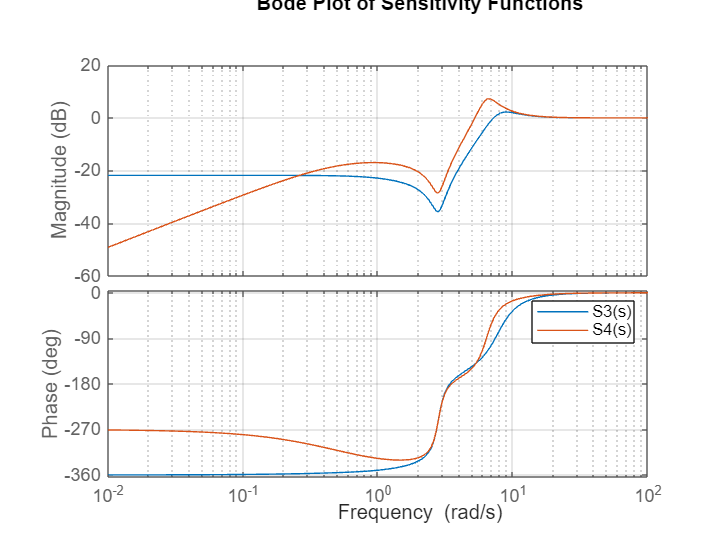

% Define s and plant G(s)
s = tf('s');
d_phi = 0.2;  % Given damping

% Define design parameters for C3
alpha3 = 0.1;
fc = 10;
wc = 2*pi*fc;
omega_L3 = wc;

% Compute the magnitude of the lead compensator part at wc
lead_mag3 = abs((alpha3*omega_L3*1i*wc + 1) / ((1/(alpha3*omega_L3))*1i*wc + 1));

% Get plant magnitude at wc
[G_mag, ~] = bode(G, wc);
G_mag = G_mag(:);  % ensure scalar

% Solve for proportional gain P3
P3 = 1 / (G_mag * lead_mag3);

% Define C3(s)
C3 = P3 * ((alpha3/omega_L3*s + 1) / ((1/(alpha3*omega_L3))*s + 1));

% Define design parameters for C4
alpha4 = 0.2;
omega_L4 = wc;
omega_I4 = 2*pi*0.1;  % PI zero frequency well below 1 Hz

% Compute magnitude of lead part at wc for C4
lead_mag4 = abs((alpha4*omega_L4*1i*wc + 1) / ((1/(alpha4*omega_L4))*1i*wc + 1));

% Compute magnitude of PI part at wc
pi_mag4 = abs((omega_I4*1i*wc + 1) / (1i*wc));

% Use the plant magnitude from before (G_mag) at wc

% Solve for proportional gain P4
P4 = 1 / (G_mag * lead_mag4 * pi_mag4);

% Define C4(s)
C4 = P4 * ((alpha4/omega_L4*s + 1) / ((1/(alpha4*omega_L4))*s + 1)) * ((omega_I4 + s) / s);
% Open-loop transfer functions for controllers 3 and 4
L3 = C3 * G;
L4 = C4 * G;

% Sensitivity and process sensitivity functions
S3 = 1/(1+L3);
PS3 = G/(1+L3);

S4 = 1/(1+L4);
PS4 = G/(1+L4);

% Bode plot for sensitivity functions S3 and S4
figure;
bode(S3, S4);
grid on;
legend('S3(s)','S4(s)');
title('Bode Plot of Sensitivity Functions');

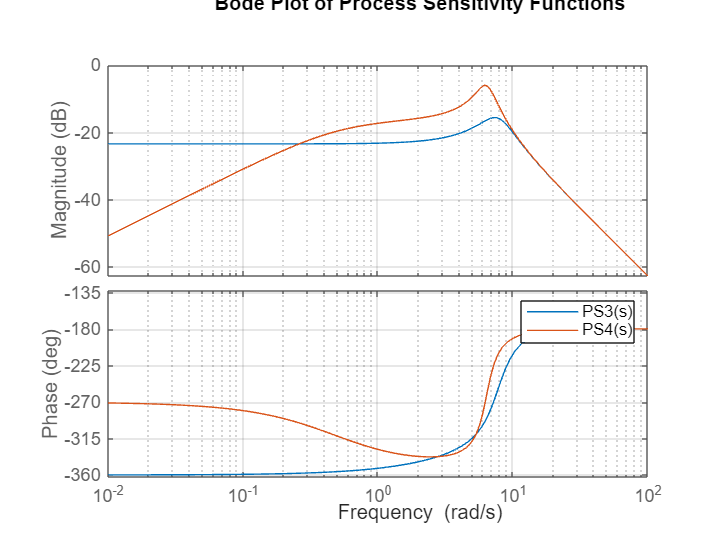


% Bode plot for process sensitivity functions PS3 and PS4
figure;
bode(PS3, PS4);
grid on;
legend('PS3(s)','PS4(s)');
title('Bode Plot of Process Sensitivity Functions');

## Question i)

Perform a simulation of the closed-loop system using controller C3(s) and C4(s). Use a ref�erence: r(t) = Ar sin(2π fr t) over a time-window of t ∈ [0,5] given input frequency fr = 1 Hz and amplitude Ar = 1.0 rad (all other signals are omitted). Plot both error signals e3(t) and e4(t) in the same figure. Which controller, C3(s) or C4(s), is better for tracking this particular reference and why? In your answer, make reference to your results in question (h). Hint: use the Matlab command y = lsim(sys,u,t) to simulate custom input signals.

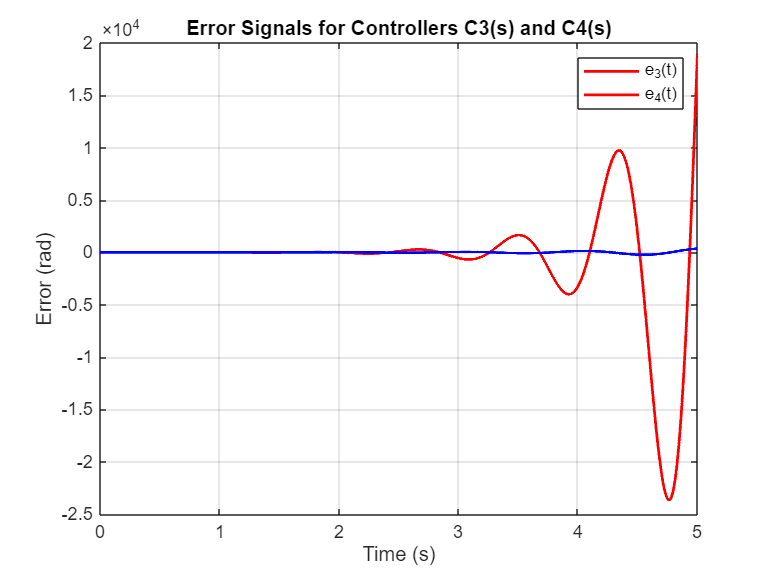

t = 0:0.001:5;                % Time vector for simulation
Ar = 1.0;                     
fr = 1;                       
r = Ar * sin(2*pi*fr*t);      % Reference signal r(t)

% Closed-loop systems
T3 = feedback(C3*G, 1);
T4 = feedback(C4*G, 1);

y3 = lsim(T3, r, t);   % Output of system with C3(s)
y4 = lsim(T4, r, t);   % Output of system with C4(s)

e3 = r - y3;  % Error signal for system with C3(s)
e4 = r - y4;  % Error signal for system with C4(s)

figure;
plot(t, e3, 'r', t, e4, 'b', 'LineWidth', 1.5);
grid on;
legend('e_3(t)', 'e_4(t)');
xlabel('Time (s)');
ylabel('Error (rad)');
title('Error Signals for Controllers C3(s) and C4(s)');

## Question j)

A disturbance d(t) = Ad sin(2π fdt) is acting onto the system with input frequency fd = 10 Hz and amplitude Ad = 10 rad (all other signals are omitted). Plot the error signals e3(t) and e4(t) over a time window of t ∈ [0,1] in the same figure. Which controller, C3(s) or C4(s), is better for suppressing this particular disturbance and why? In your answer, make reference to your results in question (h).

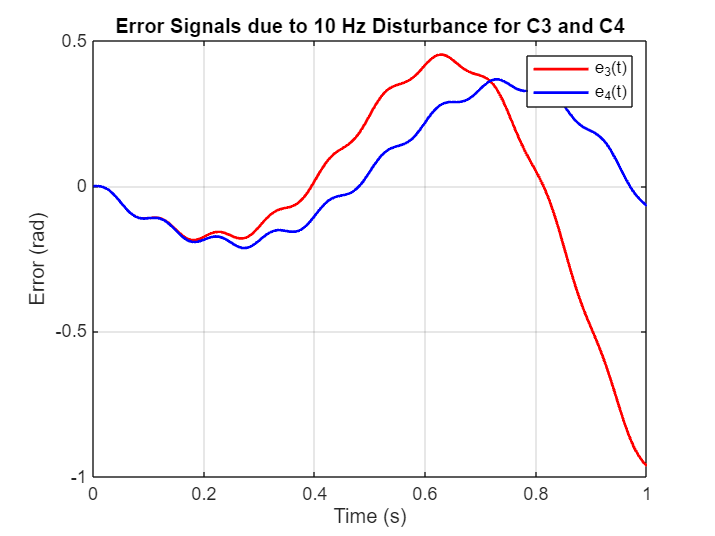

t = 0:0.001:1;         % Time vector from 0 to 1 second
fd = 10;               % disturbance frequency in Hz
Ad = 10;               % disturbance amplitude in rad
d = Ad * sin(2*pi*fd*t);  % disturbance signal d(t)

% Open-loop transfer functions assumed pre-defined
% L3 = C3 * G;
% L4 = C4 * G;

% Process sensitivity functions (from earlier calculations)
PS3 = G/(1+L3);
PS4 = G/(1+L4);

% Simulate system response to disturbance using process sensitivity functions
y3_disturbance = lsim(PS3, d, t);  % Output due to disturbance for C3
y4_disturbance = lsim(PS4, d, t);  % Output due to disturbance for C4

% Compute error signals (since r(t) = 0, error = - output)
e3 = -y3_disturbance;
e4 = -y4_disturbance;

figure;
plot(t, e3, 'r', t, e4, 'b', 'LineWidth', 1.5);
grid on;
legend('e_3(t)', 'e_4(t)');
xlabel('Time (s)');
ylabel('Error (rad)');
title('Error Signals due to 10 Hz Disturbance for C3 and C4');